First of all, we import the data of the famous MNIST dataset. We use the option "Import Data" to import a training table (as a numerical matrix) from the excel table in the workspace. Then, we divide it in labels (column vector) and pictures (each cloumn is a 28x28 image in a 784 dimensional vector).

labels_train = train(1:30000,1);
pictures_train = train(1:30000,2:end)';

labels_test = train(30001:end,1);
pictures_test = train(30001:end,2:end)';

We can plot some images to get an idea:

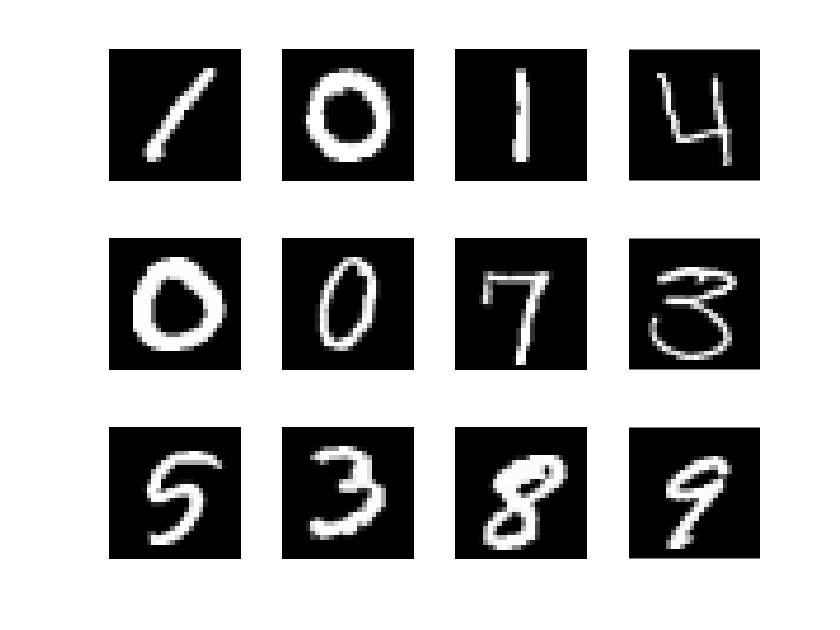

figure
for i = 1:12
    % we reshape the vector into matrix
    example = reshape(pictures_train(:,i), [28,28])';
    subplot(3,4,i);
    imshow(example,[0 255]);
end

Now we normalize the pictures: we reduce the input intensity between 0 and 255 to 0 and 1, where 0 is black and 1 is white.

pictures_train = pictures_train/255;
pictures_test = pictures_test/255;

r = [784, 200, 20, 10]; %number of nodes per layer 
nb_layers = length(r);

y_train = prepare_train_data(labels_train);

W = generate_multilayer_perceptron(r, pictures_train, y_train, 1, 30, 30000, nb_layers);

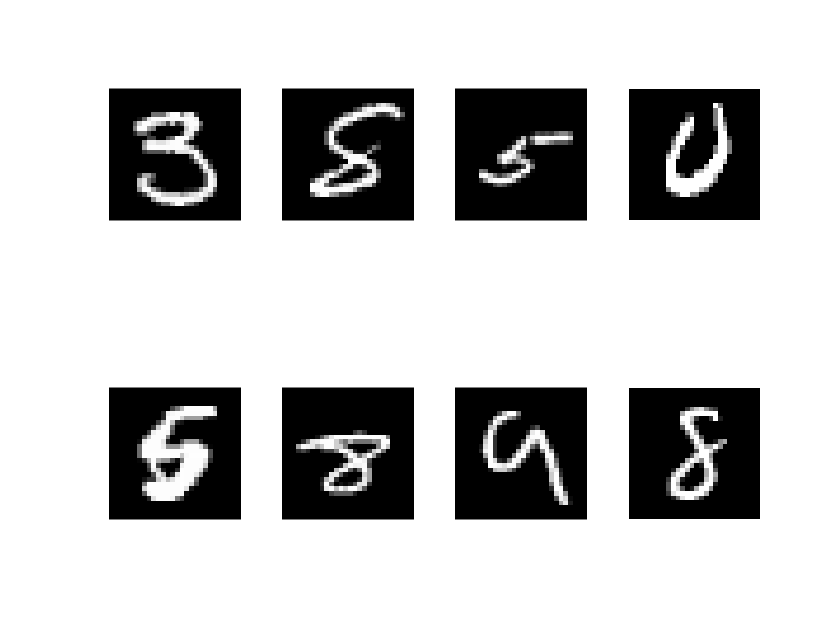

[accuracy, mistakes] = test(W,pictures_test,labels_test,nb_layers);
% accuracy in my last test: 0.9313
% plot of some of the mistakes:
figure
for i = 1:8 
    % we reshape the vector into matrix
    example = reshape(mistakes(:,i), [28,28])';
    subplot(2,4,i);
    imshow(example,[0 1]);
end

Testing the neural network with one number drawn by myself 

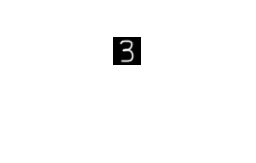

I = double(rgb2gray(imread('test.png')))/255;
figure
imshow(I);

I_vector = reshape(I',784,1);
predict(I_vector,W,nb_layers) % predicts the number in test.png

ans = 3

Values of the weights in the first layer: there is no clear pattern

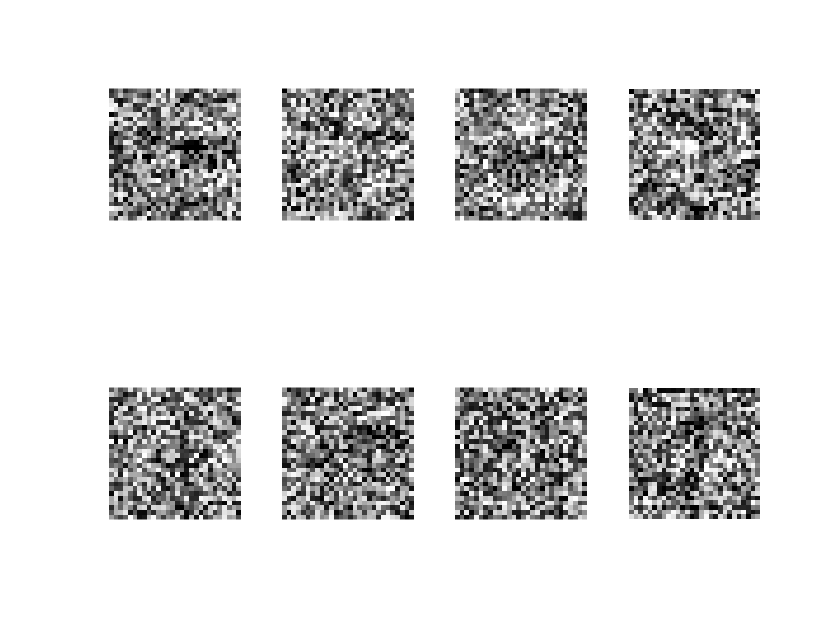

figure
for i= 1:8
    subplot(2,4,i);
    imshow(reshape(W{1}(i,1:784),28,28)',[-1,1]);
end

Function definitions:

function output = feedforward(input,weights_matrices,nb_layers)
    output = cell(1,nb_layers-1);
    for layer = 1:(nb_layers-1)
        if layer == 1
            output{layer} = sigmoid(...
                activation(add_homogeneous_coordinate(input),weights_matrices{layer}));
        else
            output{layer} = sigmoid(activation(...
                add_homogeneous_coordinate(output{layer-1}),weights_matrices{layer}));
        end
    end
end

function delta = backpropagation(outputs, weights_matrices, nb_layers, expected_value)
    delta = cell(1,nb_layers-1);
    for layer = (nb_layers-1):-1:1
        if layer == nb_layers-1
            delta{layer} = (outputs{layer}.*(1-outputs{layer}))...
                .*(outputs{layer}-expected_value);
        else
            delta{layer} = (outputs{layer}.*(1-outputs{layer}))...
                .*((weights_matrices{layer+1}(:,2:end)')*delta{layer+1});
        end
    end
end

function W = generate_multilayer_perceptron(neurons_per_layer,training_data_input,...
    training_data_output,learning_rate_0, batch_size, training_set_size, nb_layers)
    
    W = generate_random_matrices(neurons_per_layer);
    
    for batch = 1:(training_set_size/batch_size)
        
        DeltaW = update_weights_matrices(...
            training_data_input(:, (batch_size*(batch-1)+1):batch_size*batch), ...
            training_data_output(:, (batch_size*(batch-1)+1):batch_size*batch)...
            , W, nb_layers, batch_size, learning_rate_0);
        
        for layer = 1:(nb_layers-1)
            W{layer} = W{layer} - DeltaW{layer};
        end
    end
end

function [accuracy, mistakes] = test(weights_matrices, ...
    test_data_input, test_data_labels, nb_layers)

    accuracy = 0;
    mistakes = [];
    for i = 1:length(test_data_input)
        predicted = predict(test_data_input(:,i), weights_matrices, nb_layers);
        expected = test_data_labels(i);
        if predicted == expected
            accuracy = accuracy + 1;
        else
            mistakes = [mistakes, test_data_input(:,i)];
        end
    end
    accuracy = accuracy/length(test_data_labels);
end

function train_data_outputs = prepare_train_data(labels_train)
    train_data_outputs = zeros(10,length(labels_train));
    for i = 1:length(labels_train)
        train_data_outputs(labels_train(i)+1,i) = 1;
    end
end

function predicted = predict(picture, weights_matrices, nb_layers)
    outputs = feedforward(picture,weights_matrices, nb_layers);
    [~, predicted] = max(outputs{nb_layers-1});
    predicted = predicted - 1;
end

function weights_matrices = generate_random_matrices(r)
    weights_matrices = cell(1,length(r));
    for i = 1:(length(r)-1)
        weights_matrices{i} = 1-2*rand(r(i+1),r(i)+1);
    end
end

function DeltaW = update_weights_matrices(input, y_expected, ...
             weights_matrices,nb_layers, batch_size, learning_rate0)
    DeltaW = cell(1, nb_layers-1);
    for layer = 1:(nb_layers-1)
         DeltaW{layer} = zeros(size(weights_matrices{layer}));
    end
    
    for k = 1:batch_size
        outputs = feedforward(input(:,k), weights_matrices, nb_layers);
        delta = backpropagation(outputs, weights_matrices, nb_layers, y_expected(:,k));
        for layer = 1:(nb_layers-1)
            if layer == 1
                DeltaW{1} = DeltaW{1} + delta{1}*...
                    add_homogeneous_coordinate(input(:,k))';
            else
                DeltaW{layer} = DeltaW{layer} + learning_rate0*delta{layer}...
                    *add_homogeneous_coordinate(outputs{layer-1})'/batch_size;
            end
        end
    end
end

function f = sigmoid(z)
    f = 1./(1+exp(-z));
end

function E = cost(predicted, expected)
    E = 0.5*(norm(predicted-expected))^2;
end

function a = activation(input, weights)
    a = weights*input;
end

function oh = add_homogeneous_coordinate(o)
    oh = [1 ; o];
end